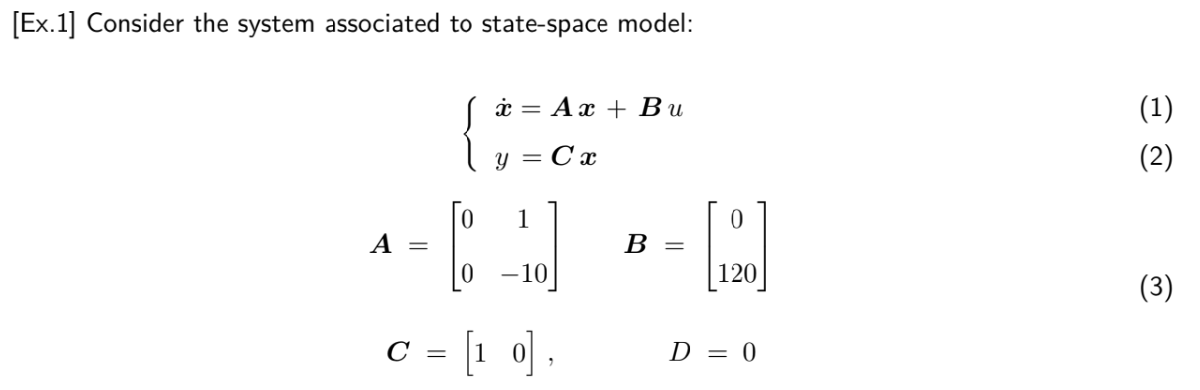

%%Implementazione sistema

clear all;
close all;
clc;

A = [0 1; 0 -10];
B = [0; 120];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);  % associa le matrici A,B,C,D alle variabili dello state space model
G = tf(sys)  % tf del processo


G =
 
     120
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties



Co = ctrb(A, B); %Controllability of state-space model
%A dynamic system is said to be controllable if it is possible to apply
%control signals that drive the system to any state within a finite
%amount of time.

if rank(Co) < size(A,1)
    error('Sistema non raggiungibile: place() non applicabile')
end

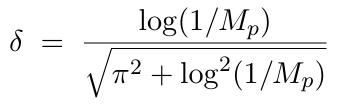

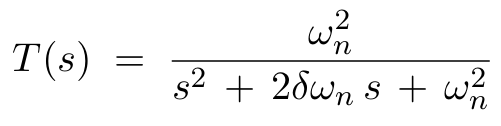

The controller poles that we have to place, for systems with two or more state variables, contain always the two poles of the closed-loop tf, and, if necessary, additional poles. In our case we only need two controller poles.

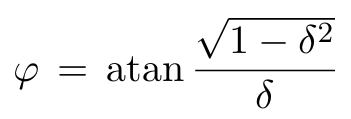

Mp = 0.2;
tr = 0.15;
omega_gc = 1.8/tr;
T_L = 1/(5 * omega_gc);
delta = (log(1/Mp))/(sqrt(pi^2+(log(1/Mp))^2));
omega_n = 1.8/tr;
phi = atan((1-delta^2)/(delta));
lambda_c_1 = omega_n*exp(1i*(-pi+phi));
lambda_c_2 = omega_n*exp(1i*(-pi-phi));

poles_des = [lambda_c_1, lambda_c_2];
K = real(place(A,B,poles_des));


% calcolo Nu e Nx
M = [A B; C D];
rhs = [0;0;1];
sol = M\rhs;

Nx = sol(1:2);% vector
Nu = sol(3);% scalar


